assert(endsWith(pwd, "non-ferromagnetic multiple material metal disk in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % length (m)
EM.Nturns = 60;

EM.z = 5.00e-3; % (m)

#### Sensor

Sensor.num = 1;
Sensor.side_length = 0.8e-3;

Sensor.position = [0e-3 2.5e-3]';

#### Model

disk.radius = 30e-3; % (m)
disk.height = 6e-3; % (m)
disk.n_r = 20; % number of elements in r direction
disk.n_z = 20; % number of elements in z direction

r = linspace(0, disk.radius, disk.n_r+1);
z = linspace(-disk.height,0, disk.n_z+1);

Model = BuildModel2D(r,z);

calculate geometry took 0.01 seconds


clear disk r z

Model.conductivity = 5.7e7 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation2D(Model, EM);

build governing equation took 27.44 seconds


#### Plot world

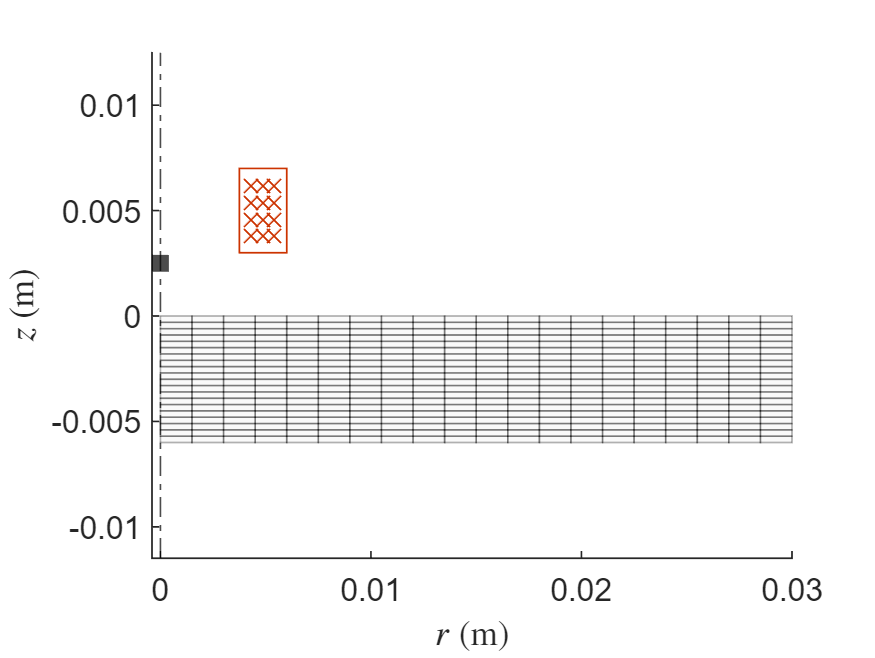

PlotWorld2D(Model, EM, Sensor);

clf

#### Time domain execitation

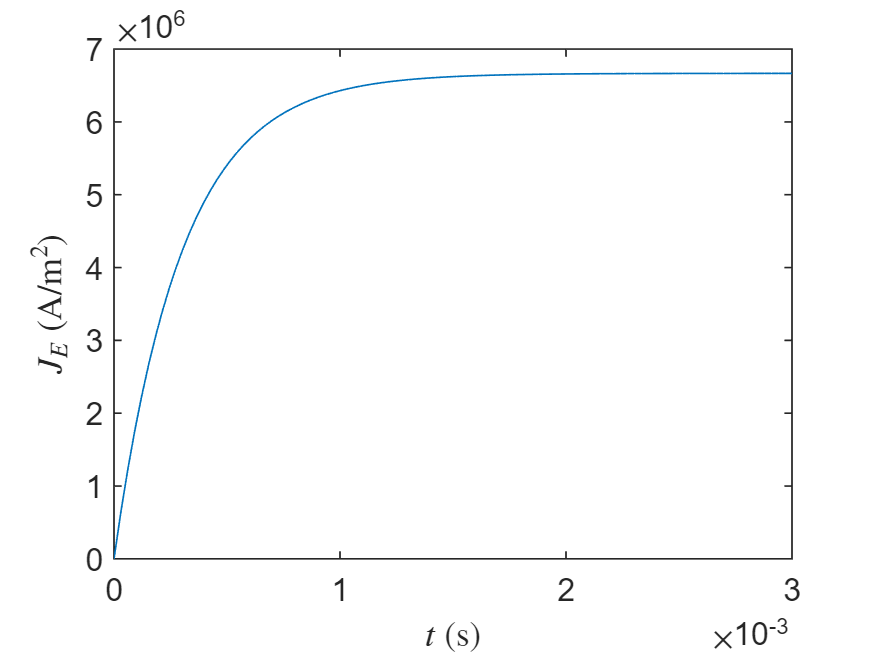

I_E_ss = 1; % (A)
J_E_ss = I_E_ss * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
tau = 3e-4; % (s)

EM.time_domain.current_density = @(t) J_E_ss * (1 - exp(-t/tau));
EM.time_domain.current_density_diff = @(t) J_E_ss/tau * exp(-t/tau);
EM.time_domain.time_span = [0, 3e-3]; % (s)

t = linspace(EM.time_domain.time_span(1), EM.time_domain.time_span(end));
plot(t, EM.time_domain.current_density(t))
ylabel('$J_E$ (A/m$^2$)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')

clf
clear I_E_ss J_E_ss tau t

#### Multiple material

materials      = ["Ti"    "Zn"   "Mo"   "Al"   "Cu"  ];
conductivities = [0.238e7 1.69e7 1.91e7 3.57e7 5.96e7];

hold on
for i = 1:numel(materials)
    material = materials(i);
    Model.conductivity = conductivities(i) * ones(1,Model.num_elms);

    mu_0 = 4*pi*1e-7; % (H/m)
    GoverningEquation.S = mu_0 * diag(Model.conductivity);

    [Model, EM, Sensor] = SolveTimeDomain2D(GoverningEquation, Model, EM, Sensor);

    t = Sensor.time_domain.t;
    B_E_r = Sensor.time_domain.B_E(1,1,:);
    B_E_z = Sensor.time_domain.B_E(2,1,:);
    B_C_r = Sensor.time_domain.B_C(1,1,:);
    B_C_z = Sensor.time_domain.B_C(2,1,:);

    plot(t, squeeze(B_C_z + B_E_z), 'DisplayName',material);
end

solve J   took 2.29 seconds
solve B_E took 0.05 seconds
solve B_C took 0.55 seconds
solve J   took 0.29 seconds
solve B_E took 0.04 seconds
solve B_C took 0.26 seconds
solve J   took 0.26 seconds
solve B_E took 0.05 seconds
solve B_C took 0.25 seconds
solve J   took 0.18 seconds
solve B_E took 0.07 seconds
solve B_C took 0.19 seconds
solve J   took 0.12 seconds
solve B_E took 0.07 seconds
solve B_C took 0.19 seconds


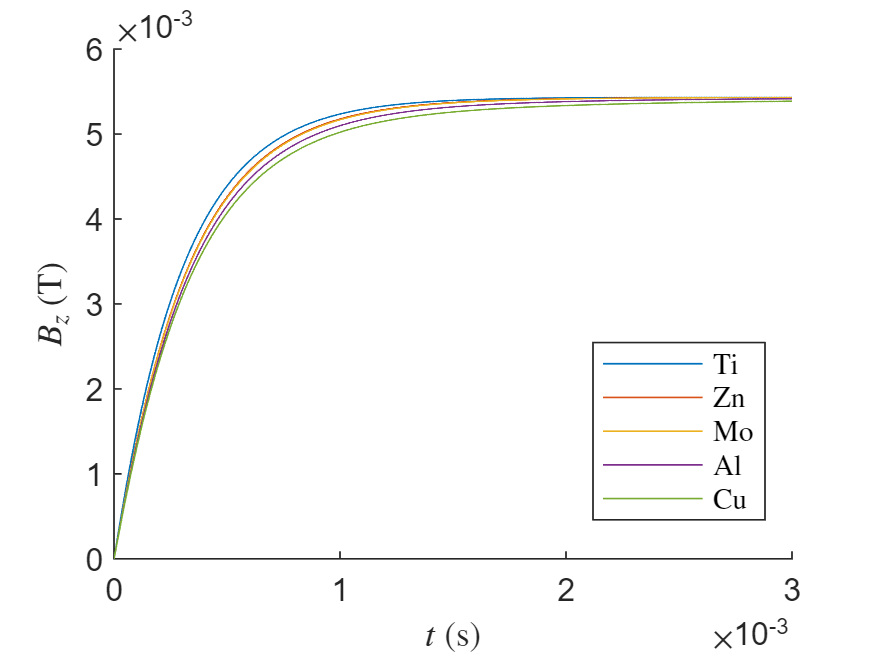

legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_z$ (T)", 'Interpreter','latex')
hold off

clf

clear materials conductivities i material mu_0 t B_E_r B_E_z B_C_r B_C_z